% generate random pulses to compare with the BER
% close all;
% clear all;
clc;

num = 1e4;
N_sample = 1;
flag_pic = 09; % set 0 2 4 6 8 10 to show the figure when SNR = 0 2 4 6 8 10 
% s = randi([0 1],1,num); % generate the signal
% save s.mat s;
load s.mat s; % use the same signal to compare
% digital signal-interpolate-analogic signal-awgn-conv-sample-threshold-ber
t = linspace(1,num,num);
h_t = ones(1,N_sample);
P_d = length(find(s==0))./num % verify P(0)=P(1)=0.5

P_d = 0.4956


s_a = zeros(1,N_sample*num); % interpolate
t_a = 1:1/N_sample:num+1;%linspace(1,num+1,N_sample*num);
t_a = t_a(1:num*N_sample);
for i = 1:1:num
    for j = 1:1:N_sample
        s_a((i-1)*N_sample+j) = s(i);
    end
end

flag_g_n = 4; % choose the way of generating the noise
for m = 1:1:6
    SNR = 2*(m-1);
% %{
    switch flag_g_n
        case 4
            s1 = awgn(s_a,SNR,'measured'); % E_s/N_0 = E_b/N_0 + 10log10(k) = 0db (k = 1,E_b/N_0 = 0)
        case 3
            s1 = awgn(s_a,SNR,db(0.5,'p'));
        case 2
            s1 = awgn(s_a,SNR);
        case 1
            sig_power = sum(s_a.^2)/length(s_a);
            N0_power = sig_power/10.^(SNR/10);
            N0 = sqrt(N0_power)*randn(1,length(s_a));
            s1 = s_a+N0;
    end
%}
    s1_1 = conv(s1,h_t); % matched filter? s(T-t) = fliplr(s1)
    s1_2 = zeros(1,num);
    for i=1:1:num
        s1_2(i) = s1_1(i*N_sample);
    end
    s1_3 = zeros(1,num);
    s1_3(s1_2/N_sample>=0.5) = 1; % page144 3.32 threshold=(a1+a2)/2
    BER(m) = length(find(s1_3-s))./num; % BER of Signal with AWGN
    BER_Q(m) = qfunc(sqrt(10.^(SNR/10)));
    
    if SNR == flag_pic
        figure;
        stem(t, s); % Original Digital-Signal
        hold on;
        plot(t_a,s_a); % Analogic-Signal
        hold on;
        plot(t_a,s1); % A-Signal with AWGN
        hold on;
        plot(t_a,s1_1(1:length(s1_1)-N_sample+1)); % A-Signal with AWGN through matched filter
        hold on;
        plot(t,s1_2); % A-Signal with AWGN through matched filter after sample
        hold on;
        stem(t, s1_3); % Signal with AWGN through threshold
        xlim([0 100]);
        % ylim([-0.25 1.25]);
        legend('Original Digital-Signal',...
            'Analogic-Signal',...
            ['A-Signal with ',num2str(SNR),'db AWGN'],...
            ['A-Signal with ',num2str(SNR),'db AWGN through matched filter'],...
            ['A-Signal with ',num2str(SNR),'db AWGN through matched filter after sample'],...
            ['Signal with ',num2str(SNR),'db AWGN through threshold']);
        hold off;
    end
end
BER

BER =     0.2429    0.1892    0.1339    0.0816    0.0401    0.0134


BER_Q

BER_Q =     0.1587    0.1040    0.0565    0.0230    0.0060    0.0008    0.1585    0.1585    0.1584    0.1584    0.1584    0.1583    0.1583    0.1583    0.1583    0.1582    0.1582    0.1582    0.1582    0.1581    0.1581    0.1581    0.1580    0.1580    0.1580    0.1580    0.1579    0.1579    0.1579    0.1578    0.1578    0.1578    0.1578    0.1577    0.1577    0.1577    0.1577    0.1576    0.1576    0.1576    0.1575    0.1575    0.1575    0.1575    0.1574    0.1574    0.1574    0.1573    0.1573    0.1573


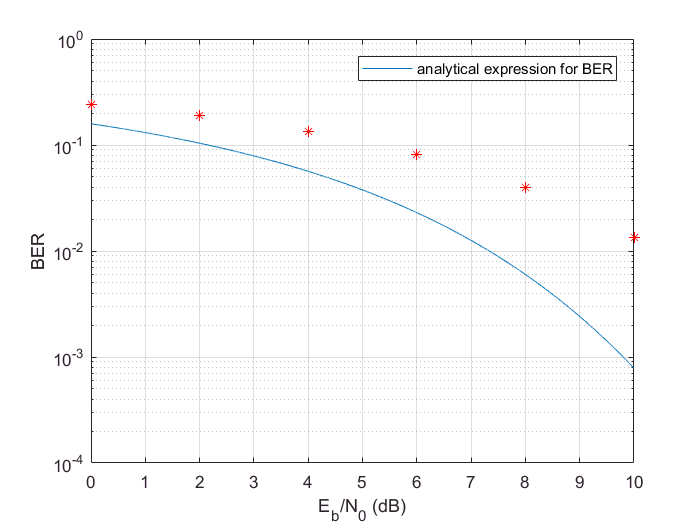


EbN0_db = linspace(0,10,num);
EbN0 = 10.^(EbN0_db/10);
BER_Q = qfunc(sqrt(EbN0)); % rho = 0

figure;
semilogy(EbN0_db, BER_Q);
for m = 1:1:m
    hold on;
    plot(2*(m-1),BER(m),'r*');
end
grid on;
ylabel('BER');
xlabel('E_b/N_0 (dB)');
legend('analytical expression for BER');
hold off;

return
% switch flag_g_n
%     case 1
% BER1 = BER; % generating noise by defination
%     case 2
% BER2 = BER; % awgn(s_a,SNR)
%     case 3
% BER3 = BER; % awgn(s_a,SNR,db(0.5,'p'))
%     case 4
% BER4 = BER; % awgn(s_a,SNR,'measured')
% end
eval([['BER',num2str(flag_g_n)],' = BER']);

figure;
semilogy(EbN0_db, BER_Q);
for m = 1:1:m
    hold on;
    plot(2*(m-1),BER1(m),'r*');
    hold on;
    plot(2*(m-1),BER2(m),'ro');
    hold on;
    plot(2*(m-1),BER3(m),'y*');
    hold on;
    plot(2*(m-1),BER4(m),'yo');
end
grid on;
ylabel('BER');
xlabel('E_b/N_0 (dB)');
title('expression for BER');
legend('analytical expression for BER',...
    'generating noise by defination',...
    'awgn(s_a,SNR)',...
    'awgn(s_a,SNR,db(0.5,''p'',))',...
    'awgn(s_a,SNR,''measured'')');
hold off;

figure;
stem(t, s); % Original Digital-Signal
hold on;
plot(t_a,s_a); % Analogic-Signal
xlim([0 20]);
ylim([-0.25 1.25]);
legend('Original Digital-Signal:s',...
    'Analogic-Signal:s_a');
hold off;





